### Control loops:

- for loop:

x = ones(1,10);
for n = 2:6
    x(n) = 2 * x(n - 1);
end
x

x =      1     2     4     8    16    32     1     1     1     1


- while loop:

n = 1;
nFactorial = 1;
while nFactorial < 1e100
    n = n + 1;
    nFactorial = nFactorial * n;
end
nFactorial

nFactorial = 1.1979e+100

### Defining a function:

- with one output:

function ave = calculateAverage(x)
    ave = sum(x(:))/numel(x);  %e.g.

ave = 50

end
% Call the function from the command line.
z = 1:99;
ave = calculateAverage(z)

- with multiple outputs:

function [m,s] = stat(x)
    n = length(x);

ave = 47.3400

stdev = 29.4124

    m = sum(x)/n;
    s = sqrt(sum((x-m).^2/n));
end
% Call the function from the command line.
values = [12.7, 45.4, 98.9, 26.6, 53.1];
[ave,stdev] = stat(values)

Local Functions

- **Definition**: Functions that are defined within a script or another function file.

- **Scope**: They are accessible only within the file where they are defined.

Global Functions

- **Definition**: Functions that are defined in their own `.m` file, with the file name matching the function name.

- **Scope**: They are accessible from any script or function in MATLAB, provided the file is on the MATLAB path.

For example, create a function file named `mystats.m` that contains a main function, `mystats`, and two local functions, `mymean` and `mymedian`.

function [avg, med] = mystats(x)
% MYSTATS global (main) function
n = length(x);

result = 1

avg = mymean(x,n);
med = mymedian(x,n);
end


result = 16

function a = mymean(v,n)
% MYMEAN Example of a local function.

a = sum(v)/n;
end

area = 0.3333


function m = mymedian(v,n)
% MYMEDIAN Another example of a local function.

w = sort(v);
if rem(n,2) == 1
    m = w((n + 1)/2);
else
    m = (w(n/2) + w(n/2 + 1))/2;
end
end

Creating a Function Handle

The `@` symbol is used to create **function handles**. A function handle is a reference to a function, allowing you to pass functions as arguments, store them in variables, or use them in operations like optimization or integration.

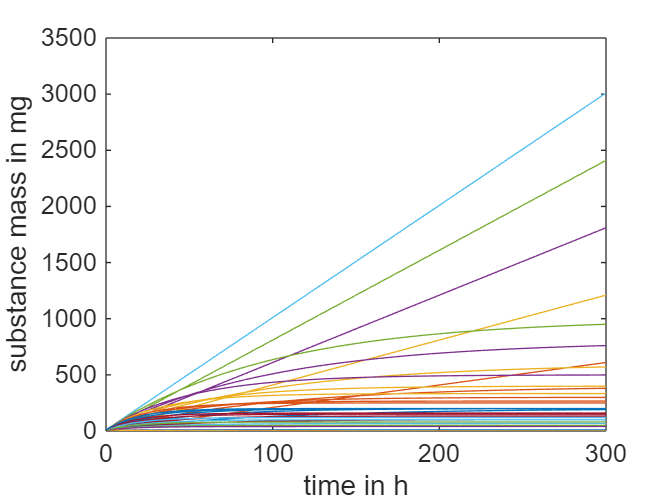

f = @sin; % Handle to the sine function
result = f(pi/2); % Calls sin(pi/2)

result

You can also use `@` to define **anonymous functions.**

f = @(x) x^2 + 2*x + 1; % Define an anonymous function
result = f(3); % Calls the function with x = 3
result

Function handles are often passed as arguments to other functions, such as `integral`, `fzero`, or `fminsearch`.

% Example: Using a function handle with integral
f = @(x) x.^2; % Anonymous function for x^2
area = integral(f, 0, 1); % Integrates x^2 from 0 to 1
area

### Solving ODEs:

**ode45** - solve nonstiff differential equations — medium order method

- Linear growth

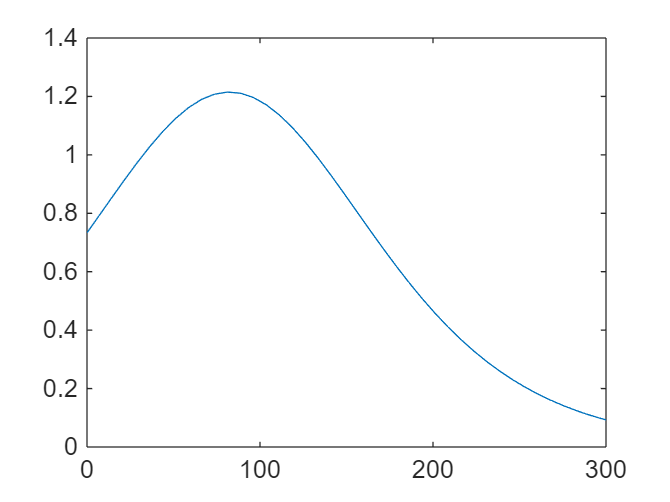

global k u %declare global variables
k = 0.05;

u=10;
y0=10;

figure;
 for (k=0:0.01:0.05) % for varying parameters k & u
    for (u=0:2:10) 
    tspan=[0 300];
    [tsim, ysim] = ode45(@bioreactor, tspan, y0); % pass the ode function handle to ode45 solver
    plot(tsim,ysim)
    xlabel('time in h')
    ylabel('substance mass in mg')
    hold on
    end
 end
    hold off
hold off

function dydt=bioreactor(t,y) % define the ode function 
global k u
dydt = -k*y+u;
end

- Logistic growth

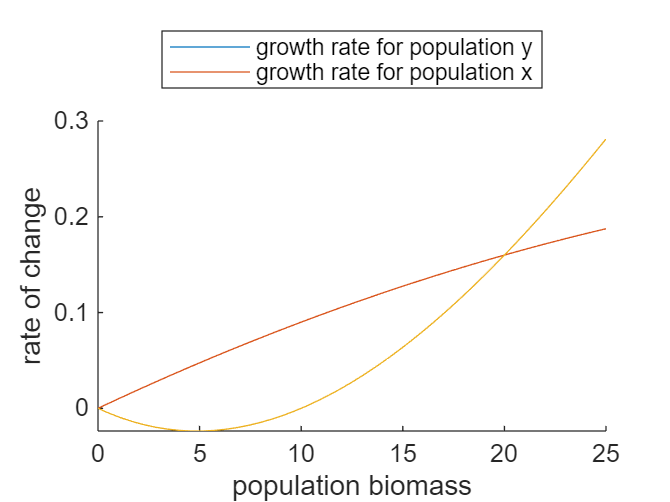

global r K

K = 270;
r = 0.018;

[tsim , ysim] = ode45(@logistic, [0 300], 50);
function dydt = logistic(t,y)
global r K
dydt = r*y.*(1-y/K);
end

figure 
plot(tsim, logistic(0, ysim))

- Logistic growth with Allee effect

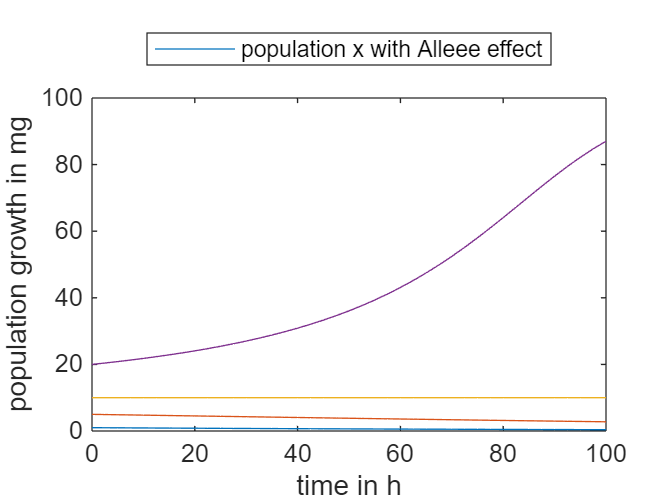

global r K A

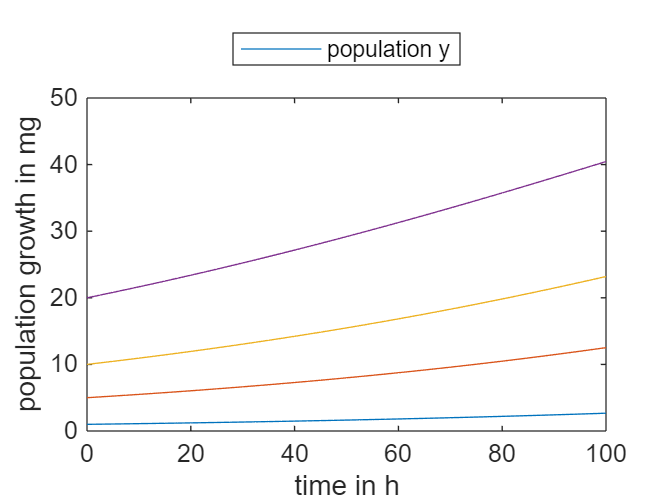

r = 0.01; 
K = 100;
A = 10;
tspan = [0, 20];
y0 = [1, 5, 10, 15, 20]; % several initial conditions

figure;
for(y0=[1, 5 , 10, 15, 20])
    tspan=[0 20];
    [ysim] = ode45(@logGrowth, tspan, y0);
    hold on
    fplot(@(ysim) r*ysim*(1-ysim/K), [0 25]) 

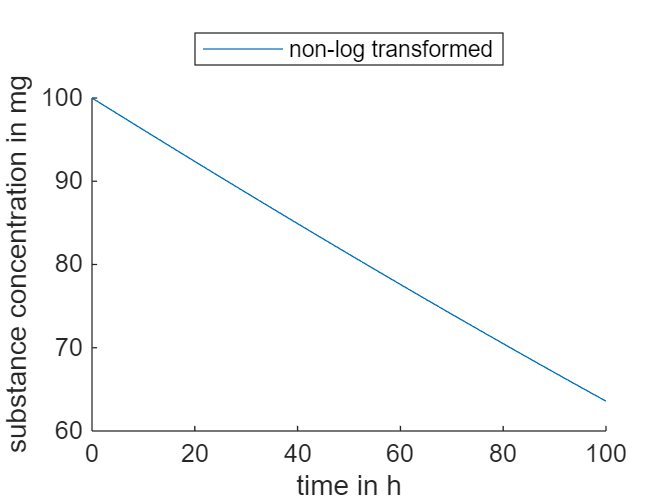


    [xsim] = ode45(@logGrowthA, tspan, y0);
    fplot(@(xsim) r*xsim*(xsim/A-1)*(1-xsim/K), [0 25])
    xlabel("population biomass")
    ylabel("rate of change")
    legend("growth rate for population y", "growth rate for population x", "Location","northoutside")
   
end
hold off

figure;
for(y0=[1,5,10,20])
    tspan=[0 100];
    [tsim, xsim] = ode45(@logGrowthA, tspan, y0);
    plot(tsim,xsim)
    xlabel('time in h')
    ylabel('population growth in mg')
    legend("population x with Alleee effect", "Location","northoutside")
    hold on
end
hold off

figure;
for(y0=[1,5,10,20])
    tspan=[0 100];
    [tsim, ysim] = ode45(@logGrowth, tspan, y0);

    plot(tsim,ysim)
    xlabel('time in h')
    ylabel('population growth in mg')
    legend("population y", "Location", "northoutside")
    hold on
end
hold off

function dxdt=logGrowthA(t,x) % ode function for logistic growth with allee effect
global r K A
dxdt = r*x*(x/A-1)*(1-x/K);
end

function dydt=logGrowth(t,y)
global r K
dydt = r*y*(1-y/K);
end

- Michaelis-Menten kinetics

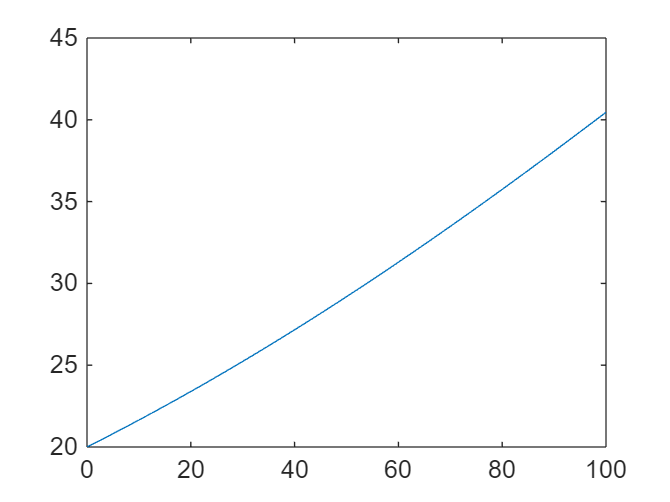

global Km v_max
v_max = 0.5;
Km = 30;
c0 = 100;
tspan = [0 100];

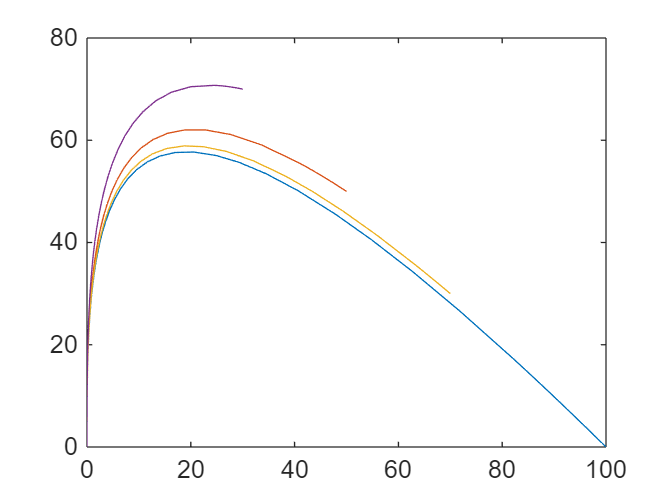

[t, c] = ode45(@MMK, tspan, c0);

figure;
hold on
plot(t,c)
% semilogy(t,c) plot with log y-axis
xlabel('time in h')
ylabel('substance concentration in mg')

legend("non-log transformed", "Location", "northoutside")
hold off

function dydt=MMK(t,y) % ode function for michelis-menten
global v_max Km
dydt = -v_max*y/(Km+y);
end



- System of ODEs

Cascade model

global k12 k20
y0=[100 0
    50 50
    70 30
    30 70];
tspan = [0 80];
y01 = [100 0
    500 0];
k12 = 0.3;
k20 = 0.1;

figure;

v =     0.4082   -0.4082    0.6963
    0.4082   -0.4082    0.1741
   -0.8165    0.8165    0.6963


lambda =    -0.5000         0         0
         0   -0.5000         0
         0         0   -0.0000


plot(tsim,ysim) % solve for all initial conditions

char_time = 1.0e+16 *

    0.0000       Inf       Inf
       Inf    0.0000       Inf
       Inf       Inf    8.4245


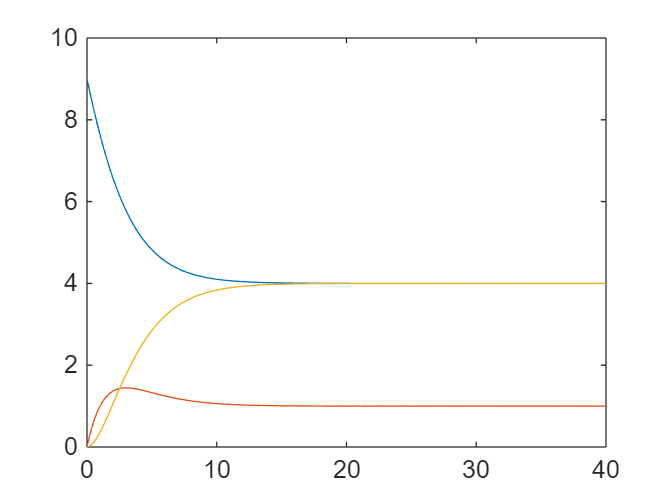


figure
for(i=1:4)
[tsim, ysim]=ode45(@bateman, tspan, y0(i,:)); 

plot(ysim(:,1), ysim(:,2)) % plot y1 vs y2

hold on
end

function dydt=bateman(t,y)
global k12 k20
y1=y(1);
y2=y(2);
dydt = [-k12*y1;
    k12*y1-k20*y2]; %explicit vector form
end

Cascade model with recycling

global A
k12 = 1/6;
k23 = 2/3;
k31 = 1/6;
tspan = [0 40];
y0=[9 0 0];

A=[-k12 0 k31
    k12 -k23 0

lb =     0.1000   15.0000    0.0100


    0 k23 -k31]; % representation of the system in matrix form

ub =     2.0000   25.0000    1.5000



[v, lambda] = eig(A) %
char_time = 1./abs(lambda) % time untill the system reaches equilibrium again, tch = 1/|lambda|
[tsim, ysim]=ode45(@tanks, tspan,y0);

r = 0.7600

y0 = 0.5000

ysimatdata =     0.5000
    1.0421
    2.1090
    4.0464
    7.0942
   10.9537
   14.6941
   17.4888
   19.1972
   20.5778


deviations =          0
    0.0421
    0.1090
    1.0464
    0.5942
   -0.0463
    0.6941
    1.4888
    0.1972
   -0.4222


r = 0.7600

y0 = 0.5000

ysimatdata =     0.5000
    1.0421
    2.1090
    4.0464
    7.0942
   10.9537
   14.6941
   17.4888
   19.1972
   20.5778


deviations =          0
    0.0421
    0.1090
    1.0464
    0.5942
   -0.0463
    0.6941
    1.4888
    0.1972
   -0.4222


r = 0.7600

y0 = 0.5000

ysimatdata =     0.5000
    1.0421
    2.1090
    4.0464
    7.0942
   10.9537
   14.6941
   17.4888
   19.1972
   20.5778


deviations =          0
    0.0421
    0.1090
    1.0464
    0.5942
   -0.0463
    0.6941
    1.4888
    0.1972
   -0.4222


r = 0.7600

y0 = 0.5000

ysimatdata =     0.5000
    1.0421
    2.1090
    4.0464
    7.0942
   10.9537
   14.6941
   17.4888
   19.1972
   20.5778


deviations =     0.0000
    0.0421
    0.1090
    1.0464
    0.5942
   -0.0463
    0.6941
    1.4888
    0.1972
   -0.4222


r = 0.7372

y0 = 0.4826

ysimatdata =     0.4826
    0.9855
    1.9598
    3.7188
    6.5177
   10.1871
   13.9455
   16.9374
   18.8764
   20.5413


deviations =    -0.0174
   -0.0145
   -0.0402
    0.7188
    0.0177
   -0.8129
   -0.0545
    0.9374
   -0.1236
   -0.4587


r = 0.7372

y0 = 0.4826

ysimatdata =     0.4826
    0.9855
    1.9598
    3.7188
    6.5177
   10.1871
   13.9455
   16.9374
   18.8764
   20.5413


deviations =    -0.0174
   -0.0145
   -0.0402
    0.7188
    0.0177
   -0.8129
   -0.0545
    0.9374
   -0.1236
   -0.4587


r = 0.7372

y0 = 0.4826

ysimatdata =     0.4826
    0.9855
    1.9598
    3.7188
    6.5177
   10.1871
   13.9455
   16.9374
   18.8764
   20.5413


deviations =    -0.0174
   -0.0145
   -0.0402
    0.7188
    0.0177
   -0.8129
   -0.0545
    0.9374
   -0.1236
   -0.4587


r = 0.7372

y0 = 0.4826

ysimatdata =     0.4826
    0.9855
    1.9598
    3.7188
    6.5177
   10.1871
   13.9455
   16.9374
   18.8764
   20.5413


deviations =    -0.0174
   -0.0145
   -0.0402
    0.7188
    0.0177
   -0.8129
   -0.0545
    0.9374
   -0.1236
   -0.4587


r = 0.7291

y0 = 0.4947

ysimatdata =     0.4947
    1.0021
    1.9772
    3.7261
    6.4992
   10.1408
   13.8996
   16.9288
   18.9190
   20.6574


deviations =    -0.0053
    0.0021
   -0.0228
    0.7261
   -0.0008
   -0.8592
   -0.1004
    0.9288
   -0.0810
   -0.3426


r = 0.7291

y0 = 0.4947

ysimatdata =     0.4947
    1.0021
    1.9772
    3.7261
    6.4992
   10.1408
   13.8996
   16.9288
   18.9190
   20.6574


deviations =    -0.0053
    0.0021
   -0.0228
    0.7261
   -0.0008
   -0.8592
   -0.1004
    0.9288
   -0.0810
   -0.3426


r = 0.7291

y0 = 0.4947

ysimatdata =     0.4947
    1.0021
    1.9772
    3.7261
    6.4992
   10.1408
   13.8996
   16.9288
   18.9190
   20.6574


deviations =    -0.0053
    0.0021
   -0.0228
    0.7261
   -0.0008
   -0.8592
   -0.1004
    0.9288
   -0.0810
   -0.3426


r = 0.7291

y0 = 0.4947

ysimatdata =     0.4947
    1.0021
    1.9772
    3.7261
    6.4992
   10.1408
   13.8996
   16.9288
   18.9190
   20.6574


deviations =    -0.0053
    0.0021
   -0.0228
    0.7261
   -0.0008
   -0.8592
   -0.1004
    0.9288
   -0.0810
   -0.3426


r = 0.7272

y0 = 0.4983

ysimatdata =     0.4983
    1.0076
    1.9843
    3.7329
    6.5022
   10.1375
   13.8932
   16.9259
   18.9235
   20.6743


deviations =    -0.0017
    0.0076
   -0.0157
    0.7329
    0.0022
   -0.8625
   -0.1068
    0.9259
   -0.0765
   -0.3257


r = 0.7272

y0 = 0.4983

ysimatdata =     0.4983
    1.0076
    1.9843
    3.7329
    6.5022
   10.1375
   13.8932
   16.9259
   18.9235
   20.6743


deviations =    -0.0017
    0.0076
   -0.0157
    0.7329
    0.0022
   -0.8625
   -0.1068
    0.9259
   -0.0765
   -0.3257


r = 0.7272

y0 = 0.4983

ysimatdata =     0.4983
    1.0076
    1.9843
    3.7329
    6.5022
   10.1375
   13.8932
   16.9259
   18.9235
   20.6743


deviations =    -0.0017
    0.0076
   -0.0157
    0.7329
    0.0022
   -0.8625
   -0.1068
    0.9259
   -0.0765
   -0.3257


r = 0.7272

y0 = 0.4983

ysimatdata =     0.4983
    1.0076
    1.9843
    3.7329
    6.5022
   10.1375
   13.8932
   16.9259
   18.9235
   20.6743


deviations =    -0.0017
    0.0076
   -0.0157
    0.7329
    0.0022
   -0.8625
   -0.1068
    0.9259
   -0.0765
   -0.3257


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0079
    1.9847
    3.7332
    6.5021
   10.1367
   13.8923
   16.9254
   18.9238
   20.6759


deviations =    -0.0014
    0.0079
   -0.0153
    0.7332
    0.0021
   -0.8633
   -0.1077
    0.9254
   -0.0762
   -0.3241


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0079
    1.9847
    3.7332
    6.5021
   10.1367
   13.8923
   16.9254
   18.9238
   20.6759


deviations =    -0.0014
    0.0079
   -0.0153
    0.7332
    0.0021
   -0.8633
   -0.1077
    0.9254
   -0.0762
   -0.3241


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0079
    1.9847
    3.7332
    6.5021
   10.1367
   13.8923
   16.9254
   18.9238
   20.6759


deviations =    -0.0014
    0.0079
   -0.0153
    0.7332
    0.0021
   -0.8633
   -0.1077
    0.9254
   -0.0762
   -0.3241


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0079
    1.9847
    3.7332
    6.5021
   10.1367
   13.8923
   16.9254
   18.9238
   20.6759


deviations =    -0.0014
    0.0079
   -0.0153
    0.7332
    0.0021
   -0.8633
   -0.1077
    0.9254
   -0.0762
   -0.3241


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0080
    1.9848
    3.7333
    6.5021
   10.1366
   13.8922
   16.9253
   18.9238
   20.6760


deviations =    -0.0014
    0.0080
   -0.0152
    0.7333
    0.0021
   -0.8634
   -0.1078
    0.9253
   -0.0762
   -0.3240


r = 0.7271

y0 = 0.4986

ysimatdata =     0.4986
    1.0080
    1.9848
    3.7333
    6.5021
   10.1366
   13.8922
   16.9253
   18.9238
   20.6760


deviations =    -0.0014
    0.0080
   -0.0152
    0.7333
    0.0021
   -0.8634
   -0.1078
    0.9253
   -0.0762
   -0.3240


r = 0.7271

y0 = 0.4986

ysimatdata = 10×1
    0.4986
    1.0080
    1.9848
    3.7333
    6.5021
   10.1366
   13.8922
   16.9253
   18.9238
   20.6760


deviations = 10×1
   -0.0014
    0.0080
   -0.0152
    0.7333
    0.0021
   -0.8634
   -0.1078
    0.9253
   -0.0762
   -0.3240


r = 0.7271

y0 = 0.4986

ysimatdata = 10×1
    0.4986
    1.0080
    1.9848
    3.7333
    6.5021
   10.1366
   13.8922
   16.9253
   18.9238
   20.6760


deviations = 10×1
   -0.0014
    0.0080
   -0.0152
    0.7333
    0.0021
   -0.8634
   -0.1078
    0.9253
   -0.0762
   -0.3240



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x = 1×3
    0.7271   21.2753    0.4986


resnorm = 2.2620

residual = 10×1
   -0.0014
    0.0080
   -0.0152
    0.7333
    0.0021
   -0.8634
   -0.1078
    0.9253
   -0.0762
   -0.3240


exitflag = 3

output = struct with fields:
      firstorderopt: 4.0058e-04
         iterations: 5
          funcCount: 24
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 1.3147e-04
            message: 'Local minimum possible.↵↵lsqnonlin stopped because the final change in the sum of squares relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative sum of squares (r) is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
       bestfeasible: []
    constrviolation: []


lambda = struct with fields:
         lower: [3×1 double]
         upper: [3×1 double]
         eqlin: []
       ineqlin: []
      eqnonlin: []
    ineqnonlin: []


jacobian = 10×3 sparse double matrix (28 nonzeros)
   (2,1)       0.9484
   (3,1)       3.5787
   (4,1)       9.2037
   (5,1)      18.0234
   (6,1)      26.5080
   (7,1)      28.9222
   (8,1)      24.2389
   (9,1)      16.7514
  (10,1)       5.8244
   (2,2)       0.0012
   (3,2)       0.0067
   (4,2)       0.0274
   (5,2)       0.0884
   (6,2)       0.2213
   (7,2)       0.4212
   (8,2)       0.6291
   (9,2)       0.7889
  (10,2)       0.9438
   (1,3)       1.0000
   (2,3)       1.9724
   (3,3)       3.6959
   (4,3)       6.3200
   (5,3)       9.2665
   (6,3)      10.8891
   (7,3)       9.8913
   (8,3)       7.1013
   (9,3)       4.2930
  (10,3)       1.1961


r = 0.7271

figure 
plot(tsim, ysim);

y0 = 0.4986

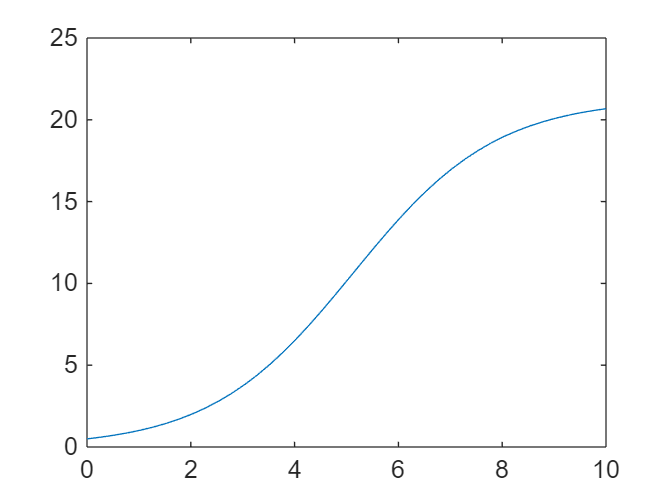


function dysdt=tanks(t,y)
global A;

dysdt = A*y;
end

### Parameter estimation

**lsqnonlin** - solve nonlinear least-squares (nonlinear data-fitting) problems.

[`x`](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_support_results_1_lsqnonlin#buuhch7_sep_shared-x) `=` `lsqnonlin``(`[`fun`](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_support_results_1_lsqnonlin#buuhch7-fun)`,`[`x0`](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_support_results_1_lsqnonlin#buuhch7_sep_shared-x0)`,`[`lb`](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_support_results_1_lsqnonlin#buuhch7_sep_shared-lb)`,`[`ub`](https://www.mathworks.com/help/optim/ug/lsqnonlin.html?searchHighlight=lsqnonlin&s_tid=srchtitle_support_results_1_lsqnonlin#buuhch7_sep_shared-ub)`)` defines a set of lower and upper bounds on the design variables in `x`, so that the solution is always in the range `lb `≤` x `≤` ub`. You can fix the solution component `x(i)` by specifying `lb(i) = ub(i).`

**interp1** - quaternion interpolation (table lookup).

A = [0 0.5;
    1 1 ;
    2 2; 
    3 3;
    4 6.5; 
    5 11;
    6 14;
    7 16;
    8 19; 
    10 21];

global A
%  Parameters to be estimated
r = 0.76;
K = 21;
y0 = 0.5;

% 
x0 = [r, K, y0]; % initial guess with lower and upper boundary
lb=[0.1, 15, 0.01]
ub = [2, 25, 1.5]

% pass results of optimloggrowth (deviations) onto lsqnonlin. Runs until
% reaches local minimum
[x, resnorm, residual, exitflag, output, lambda, jacobian] = lsqnonlin(@optimloggrowth, x0, lb, ub) %pass results of optimloggrowth (deviations) onto lsqnonlin
r = x(1)
K=x(2);
y0 = x(3)
tspan = [0, 10];
[tsim, ysim] = ode45(@logGrowth, tspan, y0);
plot(tsim, ysim)

function deviations = optimloggrowth(x)
global r K A
r = x(1)
K = x(2)
y0 = x(3)
tspan = [0, 10];
[tsim, ysim] = ode45(@logGrowth, tspan, y0);
ysimatdata = interp1(tsim, ysim, A(:, 1)); % get the sim y at defined (measured times)
deviations = ysimatdata - A(:,2); % compare with actual time
end
